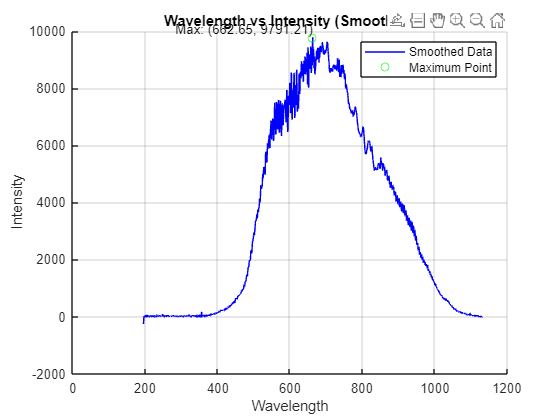

% Define the file name
filename = "C:\Users\jerub\Desktop\ECCE\Courses-Modules\Msc Project\11-dshaped fiber (without jacket)\with 0.9%nacl_HR4C58731_16-51-06-532.txt";
% Read the data from the file
data = readmatrix(filename);

% Extract the wavelength and intensity columns
wavelength = data(:, 1);
intensity = data(:, 2);

% Smooth the intensity data using the Savitzky-Golay filter
smoothed_intensity = sgolayfilt(intensity, 3, 11); % Order 3 polynomial, frame size 11

% Find the maximum intensity and the corresponding wavelength
[max_intensity, max_index] = max(smoothed_intensity);
max_wavelength = wavelength(max_index);

% Plot the raw and smoothed data
figure;
%plot(wavelength, intensity, 'r-', 'DisplayName', 'Raw Data');
hold on;
plot(wavelength, smoothed_intensity, 'b-', 'DisplayName', 'Smoothed Data');
plot(max_wavelength, max_intensity, 'go', 'DisplayName', 'Maximum Point'); % Mark the maximum point
xlabel('Wavelength');
ylabel('Intensity');
title('Wavelength vs Intensity (Smoothed)');
legend;
grid on;

% Annotate the maximum point
text(max_wavelength, max_intensity, sprintf('Max: (%.2f, %.2f)', max_wavelength, max_intensity), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');


% Display the maximum wavelength and intensity
fprintf('Maximum Intensity: %.2f at Wavelength: %.2f\n', max_intensity, max_wavelength);

Maximum Intensity: 9791.21 at Wavelength: 662.65
